clear all;
close all;

% Import Bag Data

bag = rosbag("Lvl_2_Hayden_Map_12.bag");

bagd= select(bag, 'Topic', '/fusion');

msg = readMessages(bagd, 'DataFormat', 'struct');

% Populate Desired Data Arrays

msg_ptr = 1;

time_offset = double(msg{1}.Header.Stamp.Sec) + double(msg{1}.Header.Stamp.Nsec)*(10^-9);

while msg_ptr < length(msg)+1
    time(msg_ptr) = double(msg{msg_ptr}.Header.Stamp.Sec) + double(msg{msg_ptr}.Header.Stamp.Nsec)*(10^-9);
    time_norm(msg_ptr)=time(msg_ptr)-time_offset;
    yaw(msg_ptr) = msg{msg_ptr}.Yaw;
    pitch(msg_ptr)= msg{msg_ptr}.Pitch;
    roll(msg_ptr) = msg{msg_ptr}.Roll;
    accel_x(msg_ptr) = msg{msg_ptr}.Imu.LinearAcceleration.X;
    accel_y(msg_ptr) = msg{msg_ptr}.Imu.LinearAcceleration.Y;
    accel_z(msg_ptr) = msg{msg_ptr}.Imu.LinearAcceleration.Z;
    sensor_x(msg_ptr) = msg{msg_ptr}.SensorY;
    sensor_y(msg_ptr) = msg{msg_ptr}.SensorX;
    range(msg_ptr) = double(msg{msg_ptr}.Range);
    msg_ptr=msg_ptr+1;
end



% Correct 5000 time out and 300 saturation error points
replace = find(range ==5000)

replace =    381   382   383   384   385   386   387   388   389   390   391   392   393   394   395   396   397   398   399   866   867   868   869   870   871   872   873   874   875   876   877   878   879   880   881   882   883   884   885   886   887   888   889   890   891   892   893   894   895   896


for n=1:length(replace)
    range(replace(n))=range(replace(n)-1);
end

replace = find(range ==300)

replace =     85    86    87    94    95    96    97    98    99   100   101   102   103   104   105   106   107   610   611   612   613   614   615   616   617   618   619   620   621   622   623   624   625   626   627   628   629   630   631   632   633   634   635   636   637   638   639   640   641   642


for n=1:length(replace)
    range(replace(n))=range(replace(n)-1);
end



% Compensate for drift during change in yaw
diff_yaw = diff(unwrap(yaw));
yaw_replace = find(abs(diff_yaw)>5e-3)

yaw_replace =    297   298   299   300   301   302   303   304   305   306   307   308   309   310   311   312   313   314   315   316   317   318   319   320   321   322   323   324   325   326   327   328   329   330   331   332   333   334   335   336   337   338   339   340   341   342   343   344   345   346



for n=1:length(yaw_replace)
    accel_x(yaw_replace(n))=0;
    accel_y(yaw_replace(n))=0;
end


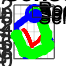


% Testing Stuff
% replace = find(abs(accel_x) < 0.1);
% accel_x(replace) = 0;
% replace = find(abs(accel_y) < 0.1);
% accel_y(replace) = 0;
% accel_x = accel_x - mean(accel_x(1:300));
% accel_y = accel_y - mean(accel_y(1:300));
% accel_x=highpass(accel_x,0.005);
% accel_y=highpass(accel_y,0.005);


% Integrate

velocity_x=cumtrapz(time_norm,accel_x);
velocity_x=velocity_x + 0.15;
velocity_y=cumtrapz(time_norm,accel_y);
velocity_z=cumtrapz(time_norm,accel_z);
x=cumtrapz(time_norm,velocity_x);
y=cumtrapz(time_norm,velocity_y);
z=cumtrapz(time_norm,velocity_z);

for n=1:length(x)
obstacle_x(n) = x(n) + range(n)/1000*cos(yaw(n));
obstacle_y(n) = y(n) + range(n)/1000*sin(yaw(n));
end


% Create Room Plot

room_points_x = [125 355 355 505 505 735 735 805 805 865 865 805 805 160 160 0 0 125 125];
room_points_y = [0 0 60 60 0 0 60 60 515 515 745 745 815 815 885 885 60 60 0];
room_points = [room_points_x/100; room_points_y/100];

% Transpose
room_points = room_points';

sensor_origin = [35 700]/100;

room_points = room_points-sensor_origin;

% Rotate Room about sensor origin
theta = deg2rad(60);

R_theta = [cos(theta) -sin(theta); sin(theta) cos(theta)];

room_points = room_points*R_theta;


figure('Name', 'Level 1 - Data Comparison', 'Position', [10 10 800 600]);

plot(room_points(:,1), room_points(:,2), 'b', 'LineWidth', 3); hold on; % room layout
plot(x,-y, 'r', "LineWidth", 2); % sensor position
% scatter(echo_points(first_nonzero,1), echo_points(first_nonzero,2), 50, 'g', 'filled'); % plot first data point to help with orientation alignment
scatter(obstacle_x, -obstacle_y, 20, 'g', 'filled'); %obstacle position
scatter(0,0,75,'b','filled'); % sensor origin
daspect([1 1 1]);
% xlim([-4 3]); ylim([-4 3]);
xlabel('Distance (m)');
ylabel('Distance (m)');
legend('Room Outline', 'Sensor Position', 'Sensor Data Points', 'Sensor Starting Point'); % create legend
title('Level 2 Mapping - Room Outline vs Sensor Data Comparison for Hayden 425'); % create title
grid on;



% figure(1);
% hold all;
% pbaspect([1 1 1]);
% scatter(x,-y);
% scatter(obstacle_x, -obstacle_y);
% axis([-16 16 -16 16]);